# **drawPolygon**

# **fillPolygon**

Draw or fill a closed 2D shape with straight sides.

## Description

## Syntax

drawPolygon(xp,yp)

drawPolygon(xp,yp,LineSpec)

p = drawPolygon(__)

fillPolygon(c,__)

### Method

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c ** - fill color

**xp - **x-coordinate of polygon vertices 

**yp **- y-coordinate of polygon vertices 

xp, yp must be of the same size.

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure .

- p.color - line color

## Examples

### Example 1

Example 5-3 from [1] (pp 143-144).

### Example 2

figure
hold on
axis equal
% coordinates of polygon vertices
xp=[1 2 4 3];
yp=[1 3 3 1];
% plot definiting polygon vertices
scatter(xp,yp,'r')
% plot definiting polygon
plot(xp,yp,'r')
% draw curve
p = drawPolygon(xp,yp)

p = struct with fields:
       xk: [1 2 4 3 1]
       yk: [1 3 3 1 1]
    color: 'k'


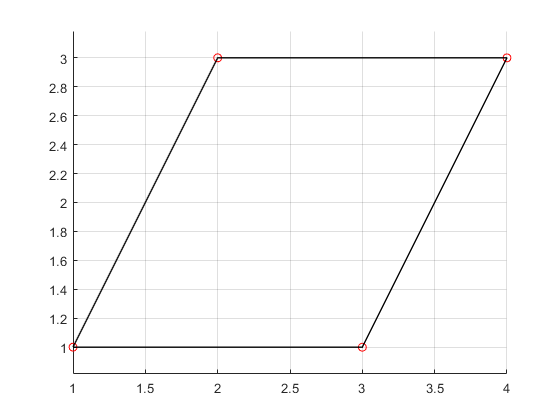

grid on

#### **Example 3**

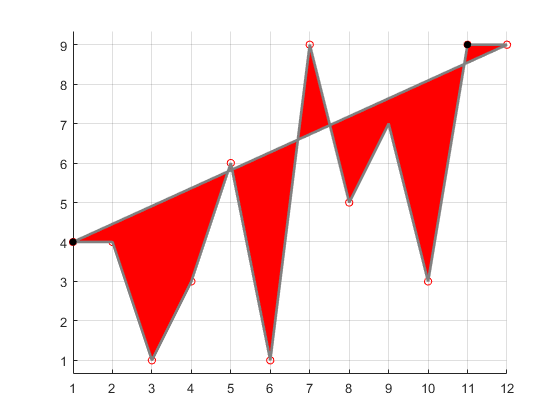

figure
axis equal
hold on
% coordinates of polygon vertices
nv = 12; % number of vertices
xv=1:nv; %randi(10,nv,1);
yv=randi(10,nv,1);
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
plot(xv,yv,'r:')
% plot calculated points
% draw curve using 50 points in gray color
b = drawPolygon(xv,yv,'LineWidth',2,'Color',[1 1 1]*0.5,'-fill','r');
% label every 10th point
scatter(xv(1:10:end),yv(1:10:end),30,'k','filled')
grid on

#### **Example 4**

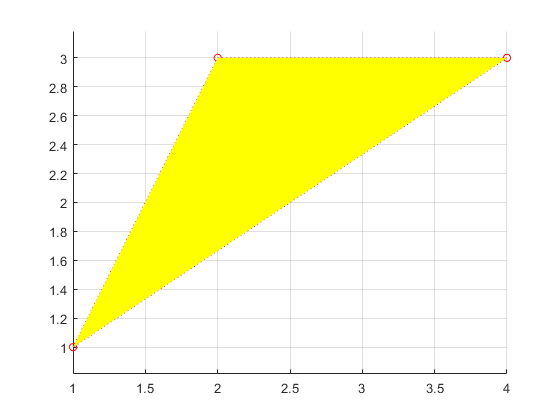

figure
axis equal
hold on
% coordinates of polygon vertices
xv = [ 1 2 4 1];
yv = [ 1 3 3 1];
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
plot(xv,yv,'r:')
% plot in gray color
b = fillPolygon('y',xv,yv);
grid on

## References